clc
clear all
df = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vSldoEABS4unIo8FZLtaLXT-mlEg5zJBRFAXG3_BqxaTd1Eq70ckcpApEHEQNju09iylNCpRuzw5lT3/pub?gid=2013391921&single=true&output=csv")

df = 31×8 table
     v1       i1        v2       i2        v3       i3        v4       i4   
    ____    _______    ____    _______    ____    _______    ____    _______

    1.65    0.00315     0.5    0.00085    0.85    0.00085       1     0.0009
    2.15    0.00425    0.75     0.0013     1.1     0.0011     1.3     0.0012
     2.3    0.00475     1.2     0.0021     1.3     0.0013     1.7     0.0015
     2.5     0.0051     1.7      0.003     1.6     0.0016     1.8     0.0016
     2.9    0.00595     1.9    0.00325     2.1      0.002    2.25      0.002
     3.2     0.0065    2.15     0.0036     2.4    0.00225     2.5     0.0022
     3.4    0.00695     2.5     0.0044     2.6     0.0025     2.8    0.00245
    3.65     0.007

di = 0.0001;

di = 1.0000e-04

dv = 0.1;

dv = 0.1000

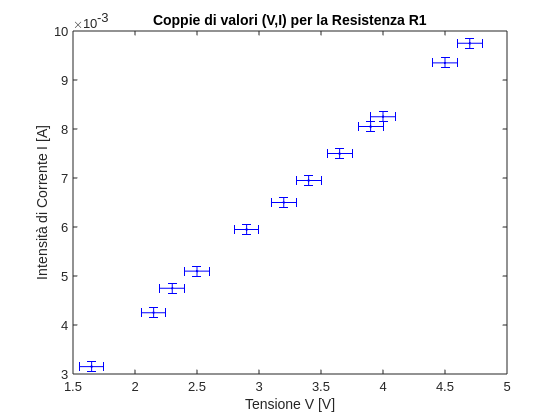

v1 = colnan(df.v1);
i1 = colnan(df.i1);

fig=figure;
errorbar(v1,i1,di,di,dv,dv,'.','Color','b')
title("Coppie di valori (V,I) per la Resistenza R1")
xlabel("Tensione V [V]")
ylabel("Intensità di Corrente I [A]")
saveas(fig,"../img/fede-1.png")

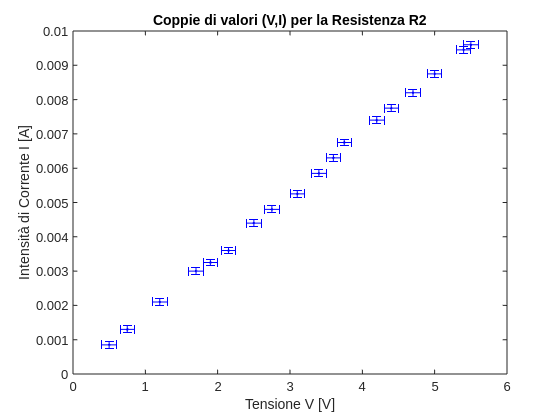

v2 = colnan(df.v2);
i2 = colnan(df.i2);

fig=figure;
errorbar(v2,i2,di,di,dv,dv,'.','Color','b')
title("Coppie di valori (V,I) per la Resistenza R2")
xlabel("Tensione V [V]")
ylabel("Intensità di Corrente I [A]")
saveas(fig,"../img/fede-2.png")

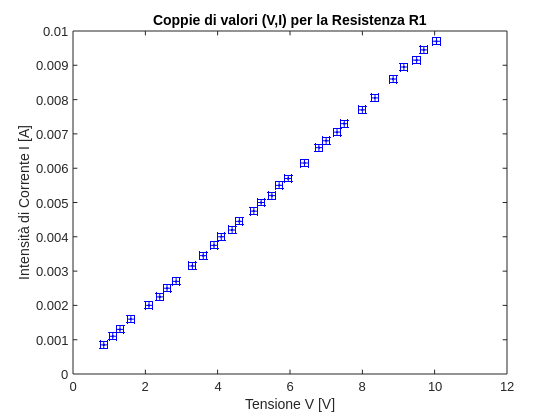


v3 = colnan(df.v3);
i3 = colnan(df.i3);

fig=figure;
errorbar(v3,i3,di,di,dv,dv,'.','Color','b')
title("Coppie di valori (V,I) per la Resistenza R1")
xlabel("Tensione V [V]")
ylabel("Intensità di Corrente I [A]")
saveas(fig,"../img/fede-3.png")

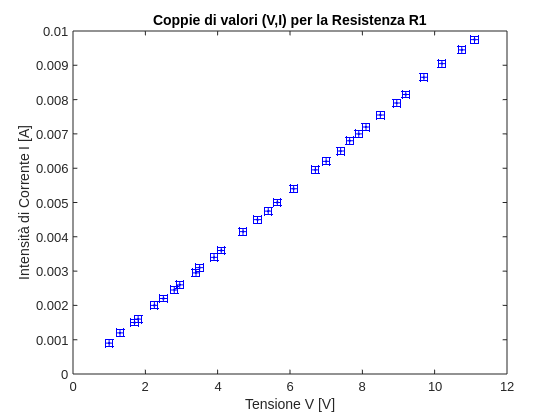


v4 = colnan(df.v4);
i4 = colnan(df.i4);

fig=figure;
errorbar(v4,i4,di,di,dv,dv,'.','Color','b')
title("Coppie di valori (V,I) per la Resistenza R1")
xlabel("Tensione V [V]")
ylabel("Intensità di Corrente I [A]")
saveas(fig,"../img/fede-4.png")

function c = colnan(x)
    ni = isnan(x);
    c = x(~ni);
end